# main関数　速度最適化を行い，B-Spline曲線を表示する．

% clear
% close all


## desired Points (X-Y)


% Q = [ 
%     0.0, 0.0;
%     1.0, 2.0;
%     3.0, 2.0;
%     3.0, 0.0;
%     5.0, 2.0;
%     6.0, 0.0;
%     ];
% 
% Q = [ 
%     0.0, 0.0;
%     0.0, 1.0;
%     0.0, 2.0;
%     0.0, 3.0;
%     0.0, 4.0;
%     0.0, 5.0;
%     5.0, 5.0;
%     5.0, 0.0;
%     0.0, 0.0;
%     ];

Q = [
    0, 0;
    5, -5;
    10, 0;
    5, 5;
    0, 10;
    5, 15;
    10, 10;
    ];

% Q = flip(Q,2);

% Q = [
%     0.0, 0.0;
%     2.5, 2.5;
%     5.0, 5.0;
%     7.5, 2.5;
%     10.0, 0.0;
%     7.5, -2.5;
%     5.0, -5.0;
%     2.5, -2.5;
%     0.0, 0.0;
%     ];
    
%  
% Q = [ 
%     3.0, 0.0;
%     6.0, 3.0;
%     3.0, 6.0;
%     0.0, 3.0;
%     3.0, 0.0;
%     ];

% Q = [ 
%     0.0,   0.0;
%     10.0, 10.0;
%     10.0,  0.0;
%     0.0,  10.0;
%     0.0,   0.0;
%     ];




n_CONTROL_POINT = length(Q);     % Number of Control Points
DEGREE = 3;              % Degree of B-Spline
n_KNOT = n_CONTROL_POINT + DEGREE + 1; % Number of Knots in Knot Vector
n_SAMPLING_CONTROL = 25;     % Number of Sampling / Control Points
n_SAMPLING = n_SAMPLING_CONTROL * (n_CONTROL_POINT-1)+1;  % Number of Sampling
SAMPLING_TIME = 0.01;        % Sampling time [s]
MAX_VELOCITY = 1.0;        % max Velocity [m/s]
MAX_ACCEL = 150;          % max Accelaration [mm/s^2]
MAX_POS_ERR = 0.01;    % max Position Error [mm]
MotorRatio = 1;     % Ratio of Motor

MASS = 5.33;
% Mass = 0;
VEL_C = 24.2020;
MAX_F = 100;


t = 0:n_SAMPLING-1;
t = t / t(end);

u = OpenUniformKnotVector(n_KNOT,DEGREE,n_CONTROL_POINT);
P = CalculateControlPoint(Q, u, DEGREE);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<


% P = [[5, 0];
%         oldP(6:9,:);
%         oldP(6:9,:);
%         oldP(6:8,:);
%         [5, 0]];

## Calculate B-spline Curve

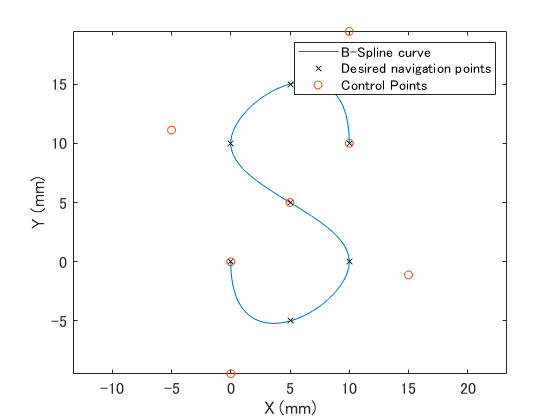

S = zeros(length(t),2);
for i = 1:length(t)
    for j =1:n_CONTROL_POINT
        b = BasisFunction(u,j,DEGREE,t(i));
        S(i,:) = S(i,:) + P(j,:)*b;
    end
end

S(1,:) = Q(1,:);
S_length = TotalLength(Q);

figure;
plot(S(:,1),S(:,2),Q(:,1),Q(:,2),'kx',P(:,1),P(:,2),'o');
set(gca, 'FontSize', 12);
xlabel('X (mm)');
ylabel('Y (mm)');
legend('B-Spline curve','Desired navigation points','Control Points');
axis equal;

% axis([-5 15 -1 20]);


## 微分値を計算

DS = zeros(n_SAMPLING,2); % 1列目：X軸，2列目：Y軸
DS_norm = zeros(n_SAMPLING, 1);
DS_2 = zeros(n_SAMPLING,2); % 1列目：X軸，2列目：Y軸
DS_2_norm = zeros(n_SAMPLING, 1);

for i = 1: n_SAMPLING
    for j =1:n_CONTROL_POINT
        b = DifBasisFunction(1,u,j,DEGREE,t(i));  
        DS(i,:) = DS(i,:) + P(j,:)*b;
        DS_norm(i) = norm(DS(i,:));
        b = DifBasisFunction(2,u,j,DEGREE,t(i));  
        DS_2(i,:) = DS_2(i,:) + P(j,:)*b;
        DS_2_norm(i) = norm(DS_2(i,:));
    end
end

n_t = n_SAMPLING;

% S(length(t):length(t) + 150,:) = S(1:151,:);
% DS(length(t):length(t) + 150,:) = DS(1:151,:);
% DS_2(length(t):length(t) + 150,:) = DS_2(1:151,:);
% DS_norm(length(t):length(t) + 150,:) = DS_norm(1:151,:);
% 
% n_t = n_SAMPLING + 150;
% 
% t = 0:n_t-1;
% t = t / t(end);

figure;
subplot(2,1,1);
plot(t, DS(:,1),'b-',t, DS(:,2),'r--',t, DS_norm,'-.');
xlabel('u');
ylabel('V(mm/min)');
legend('X-axis','Y-axis','Feed','norm(calculated)');

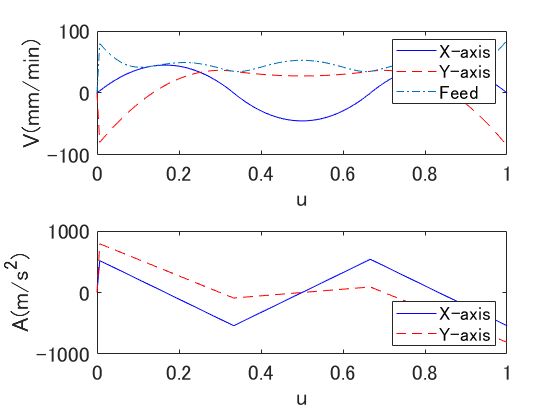

set(gca, 'FontSize', 16);


subplot(2,1,2); 
plot(t, DS_2(:,1),'b-',t, DS_2(:,2),'r--');
xlabel('u');
ylabel('A(m/s^2)');
legend('X-axis','Y-axis','Location','southeast');
set(gca, 'FontSize', 16);

% ylim([-120 120]);


## 曲率

for i = 1: n_t
    for j =1:n_CONTROL_POINT
        MatDet = [DS(i, 1), DS(i, 2);
                  DS_2(i, 1), DS_2(i, 2)];
        R(i) = abs((DS(i,1)^2+DS(i,2)^2)^(3/2) / det(MatDet));
    end
end


## 速度最適化

DS_norm(1) = 1*10^(-10);
% [V, fval, exitflag,output, cout,ceqout] = optimalVelocityXYaxis(t,DS,DS_2,DS_norm,R,Vmax,Amax,PosErrMax,nt,ts,MotorRatio,SLength);
% [V, fval, exitflag,output, cout,ceqout] = optimalVelocityXZaxis(t,DS,DS_2,DS_norm,R,Vmax,Amax,PosErrMax,Fmax,Mass,VelC,nt,ts,MotorRatio,SLength);
% [V, fval, exitflag,output, cout,ceqout] = optimalVelocity(t,DS,DS_2,DS_norm,R,Vmax,Amax,PosErrMax,nt,ts,MotorRatio,SLength);
% [V, fval, exitflag,output, cout,ceqout] = optimalVelocityCXY(t,DS,DS_2,DS_norm,R,Vmax,Amax,PosErrMax,nt,ts,MotorRatio,SLength);
% [V, fval, exitflag,output, cout,ceqout] = casadi_optimalVelocityXZaxis(t,DS,DS_2,DS_norm,R,Vmax,Amax,PosErrMax,Fmax,Mass,VelC,nt,ts,MotorRatio,SLength);
% [V, fval, exitflag,output, cout,ceqout] = casadi_optimalEnergy(t,DS,DS_2,DS_norm,R,Vmax,Amax,PosErrMax,Mass,Fmax,VelC,nt,ts,MotorRatio,SLength);

[V, fval, exitflag,output, cout,ceqout] = optimalEnergy(t,DS,DS_2,DS_norm,R,MAX_VELOCITY,MAX_ACCEL,MAX_POS_ERR,MAX_F,MASS,VEL_C,n_t,SAMPLING_TIME,MotorRatio,S_length);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     152    0.000000e+00    1.000e+00    1.463e+11
    1     308   -2.402402e+03    9.536e-01    1.296e+02    2.308e-01
    2     461   -2.369259e+03    9.047e-01    2.081e+02    1.999e-01
    3     613   -7.369901e+02    4.561e-03    1.216e+03    3.996e+00
    4     765   -8.223499e+02    3.721e-05    2.804e+02    5.455e-01
    5     917   -8.589606e+02    1.300e-06    5.025e+01    3.537e-02
    6    1069   -8.591398e+02    2.563e-07    2.197e-01    6.080e-04
    7    1221   -8.591406e+02    3.209e-09    8.310e-03    1.324e-04
    8    1374   -8.591406e+02    1.555e-09    2.513e-03    1.479e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
<a 

## 速度計算

for i = 1: n_t-1
    V(i,2) = DS(i,1)*V(i)./DS_norm(i);
    V(i,3) = DS(i,2)*V(i)./DS_norm(i);
    V(i,4) = norm(V(i,2:3));
end


## 加速度計算

Accele = zeros(n_t, 3);
for i = 2: n_t-1
%     A(i, 1) = DS_2(i,1)*(V(i)/DS_norm(i))^2 + DS(i,1)*((V(i+1)/DS_norm(i+1))^2-(V(i-1)/DS_norm(i-1))^2)/2*(t(i+1)-t(i-1));
%     A(i, 2) = DS_2(i,2)*(V(i)/DS_norm(i))^2 + DS(i,2)*((V(i+1)/DS_norm(i+1))^2-(V(i-1)/DS_norm(i-1))^2)/2*(t(i+1)-t(i-1));
    
    Accele(i, 3) = (V(i+1)^2-V(i)^2) / 2*DS_norm(i)*(t(i+1)-t(i));
    Accele(i, 1) = -(DS_2(i,1)*(V(i)/DS_norm(i))^2 + DS(i,1)*Accele(i, 3)/DS_norm(i));
    Accele(i, 2) = DS_2(i,2)*(V(i)/DS_norm(i))^2 + DS(i,2)*Accele(i, 3)/DS_norm(i);
    
    Accele2(i, 1) = DS_2(i,1)*(V(i)/DS_norm(i))^2 + DS(i,1)*((V(i+1)/DS_norm(i+1))^2-(V(i-1)/DS_norm(i-1))^2)/2*(t(i+1)-t(i-1));
    Accele2(i, 2) = DS_2(i,2)*(V(i)/DS_norm(i))^2 + DS(i,2)*((V(i+1)/DS_norm(i+1))^2-(V(i-1)/DS_norm(i-1))^2)/2*(t(i+1)-t(i-1));
end

    Accele2(length(Accele2(:,1))+1, 1) = 0;


## Plot result

SRound = round(S,5).*(-1);
Feed = V.*60;
FeedRound = round(Feed,1);

figure;
subplot(2,1,1);
plot(t, Feed(:,2),'b-',t, Feed(:,3),'r--',t, Feed(:,1),'-.');
xlabel('u');
ylabel('V(mm/min)');
legend('X-axis','Y-axis','Feed','norm(calculated)');

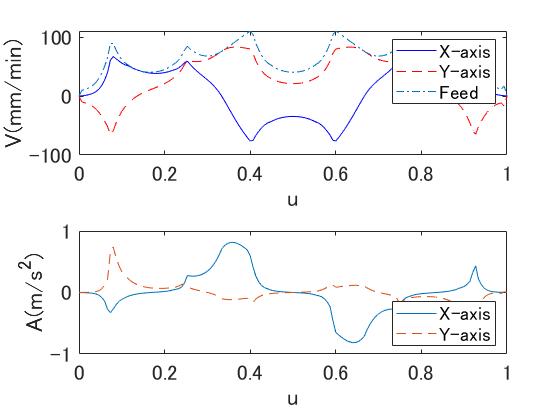

set(gca, 'FontSize', 16);


subplot(2,1,2); 
plot(t, Accele(:,1),t, Accele(:,2),'--');
xlabel('u');
ylabel('A(m/s^2)');
legend('X-axis','Y-axis','Location','southeast');
set(gca, 'FontSize', 16);

% ylim([-120 120]);

% subplot(2,1,2); 
% plot(t, Accele2);
% xlabel('t');
% ylabel('A(m/s)');
% legend('X-axis','Y-axis');

% figure
% plot(t,DS(:, 1), t, DS(:, 2));
% xlabel('t');
% ylabel('dC/du');
% legend('dX','dY','d2X','d2Y');
% 
% figure
% plot(t,DS_2(:, 1), t, DS_2(:, 2));
% xlabel('t');
% ylabel('d^2C/du^2');
% legend('X','Y');



## インプットデータを作成

n_MULTIPLE = 10;
dt = 0.01;
INPUT_TIME_END = 30;
t = 0:dt:INPUT_TIME_END;

## 一定速度のインプットデータを作成

CONST_VELOCITY = 0.45;
WIDTH_INDEX = 20;
WAIT_INDEX = 30;

% CONST_DATA.STANDBY_INDEX = 200;
% CONST_DATA.START_INDEX = 2214;
% CONST_DATA.MULT_START_INDEX = 2214;
% CONST_DATA.MULT_END_INDEX = 2364;
% CONST_DATA.END_INDEX = 2364;

CONST_DATA.STANDBY_INDEX = 200;
CONST_DATA.START_INDEX = 2217 - WAIT_INDEX;
CONST_DATA.MULT_START_INDEX = 2217 - WAIT_INDEX;
CONST_DATA.MULT_END_INDEX = 2364 + WAIT_INDEX; 
CONST_DATA.END_INDEX = 2364 + WAIT_INDEX;


useConstVelocity = V(1:151,:);
useConstPosition = S(1:151,:);

Const.Pos = zeros(length(t), 2);
Const.Vel = zeros(length(t), 3);
Const.NormVel = zeros(length(useConstVelocity(:,1)),3);

Const.NormVel(:, 3) = CONST_VELOCITY;

for i = 1:WIDTH_INDEX
    Const.NormVel(i, 3) = CONST_VELOCITY * (1 - cos((i-1) * pi/(WIDTH_INDEX-1)))/2;
end

for i = 1:WIDTH_INDEX
    Const.NormVel(i+length(useConstVelocity(:,1))-WIDTH_INDEX, 3) = CONST_VELOCITY * (1 + cos((i-1) * pi/(WIDTH_INDEX-1)))/2;
end


j = 4;
JUDGE_AXIS = 1;

for i = 1:length(t)
    if j > length(Const.NormVel(:,1))-1
        Const.Pos(i,:) = useConstPosition(1,:);
        Const.Vel(i,:) = 0;
        
    else
        orientation = (useConstPosition(j+1,:) - useConstPosition(j,:))./norm(useConstPosition(j+1,:) - useConstPosition(j,:));
        Const.NormVel(j,1:2) = orientation * Const.NormVel(j,3);

        if i == 1
            Const.Pos(1,:) = useConstPosition(1,:);
            Const.Vel(1,1:2) = [0, 0];
        elseif Const.NormVel(j,JUDGE_AXIS) < 0
            Const.Pos(i,:) = Const.Pos(i-1,:) + Const.NormVel(j,1:2).*dt;
            Const.Vel(i,1:2) = Const.NormVel(j,1:2);
            
            if Const.Pos(i,JUDGE_AXIS) < useConstPosition(j,JUDGE_AXIS)
                if j < length(Const.Vel(:,1))
                    j = j+1;
                end
                Const.Pos(i,:) = useConstPosition(j,:);
            end

        elseif Const.NormVel(j,JUDGE_AXIS) > 0
            Const.Pos(i,:) = Const.Pos(i-1,:) + Const.NormVel(j,1:2).*dt;
            Const.Vel(i,1:2) = Const.NormVel(j,1:2);

            if Const.Pos(i,JUDGE_AXIS) > useConstPosition(j,JUDGE_AXIS)
                if j < length(Const.Vel(:,1))
                    j = j+1;
                end
                Const.Pos(i,:) = useConstPosition(j,:);
            end
        elseif Const.NormVel(j,JUDGE_AXIS) == 0
            if j < length(Const.Vel(:,1))
                j = j+1;
            end            
        end        
    end
end

for i = 1:length(Const.Vel(:,1))
    Const.Vel(i,3) = norm(Const.Vel(i, 1:2));
end


Const.Vel(1:CONST_DATA.START_INDEX+WAIT_INDEX,:) = zeros(CONST_DATA.START_INDEX+WAIT_INDEX,3);
Const.Pos(1:CONST_DATA.START_INDEX+WAIT_INDEX,:) = zeros(CONST_DATA.START_INDEX+WAIT_INDEX,2);

Const.Vel(CONST_DATA.END_INDEX-WAIT_INDEX:length(t),:) = zeros(length(t) - CONST_DATA.END_INDEX + WAIT_INDEX+1,3);
Const.Pos(CONST_DATA.END_INDEX-WAIT_INDEX:length(t),:) = Const.Pos(CONST_DATA.END_INDEX-WAIT_INDEX-1,:).*ones(length(t) - CONST_DATA.END_INDEX + WAIT_INDEX+1,2);


figure;
subplot(3,1,1);
plot(t,Const.Vel(:,1),'b-',t,Const.Vel(:,2),'r--');
xlabel('t');
ylabel('V(m/s)');
legend('X-axis','Y-axis','Feed','norm(calculated)');

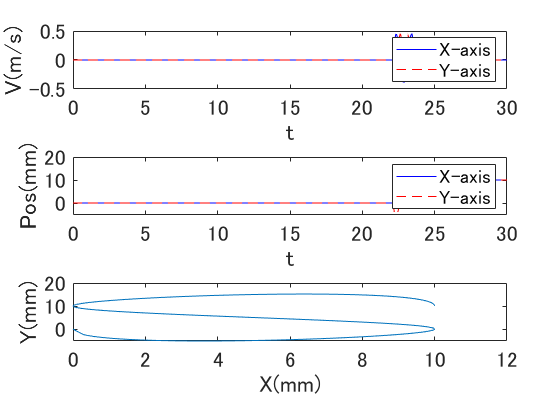

set(gca, 'FontSize', 16);

subplot(3,1,2); 
plot(t,Const.Pos(:,1),'b-',t,Const.Pos(:,2),'r--');
xlabel('t');
ylabel('Pos(mm)');
legend('X-axis','Y-axis','Location','southeast');
set(gca, 'FontSize', 16);

subplot(3,1,3); 
plot(Const.Pos(:,1),Const.Pos(:,2));
xlabel('X(mm)');
ylabel('Y(mm)');
% legend('X-axis','Y-axis','Location','southeast');
set(gca, 'FontSize', 16);



[inputConstPosition, inputConstVelocity] = makeMaltipleInput(t,n_MULTIPLE,CONST_DATA,Const);

diff = CONST_DATA.MULT_END_INDEX - CONST_DATA.MULT_START_INDEX + 1;
for k = 1:(n_MULTIPLE)/2
    inputConstPosition(CONST_DATA.STANDBY_INDEX+(k*2)*diff-7:CONST_DATA.STANDBY_INDEX+(k*2)*diff+diff-8, 2:3) ...
        = flip(inputConstPosition(CONST_DATA.STANDBY_INDEX+(k*2)*diff-7:CONST_DATA.STANDBY_INDEX+(k*2)*diff+diff-8, 2:3),1); 
    inputConstVelocity(CONST_DATA.STANDBY_INDEX+(k*2)*diff-7:CONST_DATA.STANDBY_INDEX+(k*2)*diff+diff-8, 2:3) ...
        = - flip(inputConstVelocity(CONST_DATA.STANDBY_INDEX+(k*2)*diff-7:CONST_DATA.STANDBY_INDEX+(k*2)*diff+diff-8, 2:3),1); 
end

inputConstPosition(:,2:3) = flip(inputConstPosition(:,2:3), 2);
inputConstVelocity(:,2:3) = flip(inputConstVelocity(:,2:3), 2);

figure;
subplot(3,1,1);
plot(t,inputConstVelocity(:,2),'b-',t, inputConstVelocity(:,3),'r--');
xlabel('t');
ylabel('V(m/s)');
legend('X-axis','Y-axis','norm(calculated)');

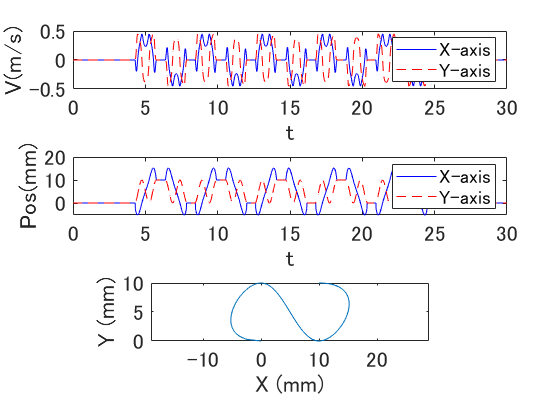

set(gca, 'FontSize', 16);

subplot(3,1,2); 
plot(t,inputConstPosition(:,2),'b-',t,inputConstPosition(:,3),'r--');
xlabel('t');
ylabel('Pos(mm)');
legend('X-axis','Y-axis','Location','southeast');
set(gca, 'FontSize', 16);

subplot(3,1,3); 
plot(inputConstPosition(:,2),inputConstPosition(:,3));
xlabel('X (mm)');
ylabel('Y (mm)');
% legend('X-axis','Y-axis','Location','southeast');
axis equal;
set(gca, 'FontSize', 16);

## 最適化した速度をインプットデータに変換

OPTI_DATA.STANDBY_INDEX = 200;
OPTI_DATA.START_INDEX = 347 - WAIT_INDEX;
OPTI_DATA.MULT_START_INDEX = 347 -  WAIT_INDEX;
OPTI_DATA.MULT_END_INDEX = 496 + WAIT_INDEX;
OPTI_DATA.END_INDEX = 496 + WAIT_INDEX;

INPUT_END_INDEX = 2203;
WIDTH_CHANGE_LENGTH = 0;

j = 2;

useVelocity = V(1:151,:);
usePosition = S(1:151,:);

Opti.Pos = zeros(length(t),2);
Opti.Vel = zeros(length(t),2);

judgeAxis = 2;

for i = 1:length(t)
    if j > length(useVelocity(:,1)-2)
        Opti.Pos(i,:) = NaN;
        Opti.Vel(i,:) = NaN;
        
    else
        if i == 1
            Opti.Pos(1,:) = usePosition(1,:);
            Opti.Vel(1,:) = useVelocity(1,2:3);
        elseif useVelocity(j,3) < 0
            Opti.Pos(i,:) = Opti.Pos(i-1,:) + useVelocity(j,2:3).*dt;
            Opti.Vel(i,:) = useVelocity(j,2:3);
            if Opti.Pos(i,judgeAxis) < usePosition(j,judgeAxis)
                if j < length(useVelocity(:,1))
                    j = j+1;
                end
                Opti.Pos(i,:) = usePosition(j,:);
            end

        elseif useVelocity(j,3) > 0
            Opti.Pos(i,:) = Opti.Pos(i-1,:) + useVelocity(j,2:3).*dt;
            Opti.Vel(i,:) = useVelocity(j,2:3);
            if Opti.Pos(i,judgeAxis) > usePosition(j,judgeAxis)
                if j < length(useVelocity(:,1))
                    j = j+1;
                end
                Opti.Pos(i,:) = usePosition(j,:);
            end
        end
        

    end
end

Opti.Vel(1:OPTI_DATA.START_INDEX+WAIT_INDEX,:) = zeros(OPTI_DATA.START_INDEX+WAIT_INDEX,2);
Opti.Pos(1:OPTI_DATA.START_INDEX+WAIT_INDEX,:) = zeros(OPTI_DATA.START_INDEX+WAIT_INDEX,2);

Opti.Vel(OPTI_DATA.END_INDEX-WAIT_INDEX-1:length(t),:) = zeros(length(t) - OPTI_DATA.END_INDEX + WAIT_INDEX+2,2);
Opti.Pos(OPTI_DATA.END_INDEX-WAIT_INDEX:length(t),:) = [10.0, 10.0].*ones(length(t) - OPTI_DATA.END_INDEX + WAIT_INDEX+1,2);

[inputOptiPosition, inputOptiVelocity] = makeMaltipleInput(t,n_MULTIPLE,OPTI_DATA,Opti);

b = flip(inputOptiPosition(611:820, 2:3),1); 
c = - flip(inputOptiVelocity(611:820, 2:3),1);

diff = OPTI_DATA.MULT_END_INDEX - OPTI_DATA.MULT_START_INDEX + 1;
for k = 1:n_MULTIPLE/2
    inputOptiPosition(OPTI_DATA.STANDBY_INDEX+(k*2)*diff-9:OPTI_DATA.STANDBY_INDEX+(k*2)*diff+diff-10, 2:3) ...
        = b; 
    inputOptiVelocity(OPTI_DATA.STANDBY_INDEX+(k*2)*diff-9:OPTI_DATA.STANDBY_INDEX+(k*2)*diff+diff-10, 2:3) ...
        = c;
    
end

% inputOptiPosition(1:WIDTH_CHANGE_LENGTH,2:3) = inputConstPosition(1:WIDTH_CHANGE_LENGTH,2:3);
% inputOptiVelocity(1:WIDTH_CHANGE_LENGTH,2:3) = inputConstVelocity(1:WIDTH_CHANGE_LENGTH,2:3);
% inputOptiPosition(INPUT_END_INDEX-WIDTH_CHANGE_LENGTH:INPUT_END_INDEX,2:3) = inputConstPosition(INPUT_END_INDEX-WIDTH_CHANGE_LENGTH:INPUT_END_INDEX,2:3);
% inputOptiVelocity(INPUT_END_INDEX-WIDTH_CHANGE_LENGTH:INPUT_END_INDEX,2:3) = inputConstVelocity(INPUT_END_INDEX-WIDTH_CHANGE_LENGTH:INPUT_END_INDEX,2:3);


inputOptiPosition(:,2:3) = flip(inputOptiPosition(:,2:3), 2);
inputOptiVelocity(:,2:3) = flip(inputOptiVelocity(:,2:3), 2);

figure;
subplot(3,1,1);
plot(t,Opti.Vel(:,1),'b-',t,Opti.Vel(:,2),'r--');
xlabel('t');
ylabel('V(m/s)');
legend('X-axis','Y-axis','Feed','norm(calculated)');

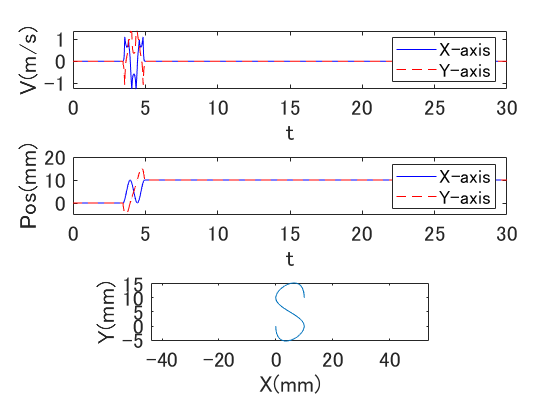

set(gca, 'FontSize', 16);

subplot(3,1,2); 
plot(t,Opti.Pos(:,1),'b-',t,Opti.Pos(:,2),'r--');
xlabel('t');
ylabel('Pos(mm)');
legend('X-axis','Y-axis','Location','southeast');
set(gca, 'FontSize', 16);

subplot(3,1,3); 
plot(Opti.Pos(:,1),Opti.Pos(:,2));
xlabel('X(mm)');
ylabel('Y(mm)');
% legend('X-axis','Y-axis','Location','southeast');
axis equal;
set(gca, 'FontSize', 16);

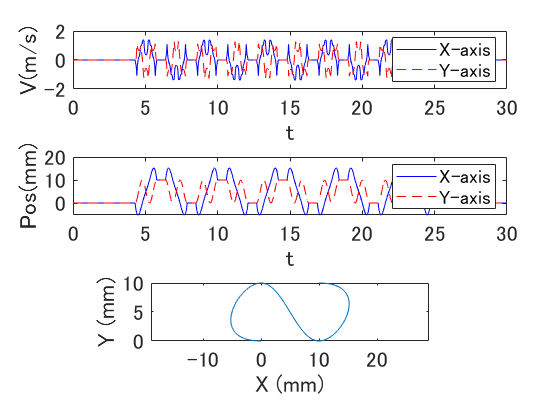


figure;

subplot(3,1,1);
plot(t,inputOptiVelocity(:,2),'b-',t, inputOptiVelocity(:,3),'r--');
xlabel('t');
ylabel('V(m/s)');
legend('X-axis','Y-axis','norm(calculated)');
set(gca, 'FontSize', 16);

subplot(3,1,2); 
plot(t,inputOptiPosition(:,2),'b-',t,inputOptiPosition(:,3),'r--');
xlabel('t');
ylabel('Pos(mm)');
legend('X-axis','Y-axis','Location','southeast');
set(gca, 'FontSize', 16);

subplot(3,1,3); 
plot(inputOptiPosition(:,2),inputOptiPosition(:,3));
xlabel('X (mm)');
ylabel('Y (mm)');
% legend('X-axis','Y-axis','Location','southeast');
axis equal;
set(gca, 'FontSize', 16);

save('S_inverse_inputdata','inputOptiPosition','inputOptiVelocity','t','inputConstPosition','inputConstVelocity');

clearvars b i Amax exitflag j k MatDet MotorRatio nKnot nQ nSampling nt output PosErrMax SLength ts u Vmax

return

figure;
plot(S(:,1),S(:,2),Q(:,1),Q(:,2),'kx');
set(gca, 'FontSize', 14);
xlabel('X (mm)');
ylabel('Y (mm)');
legend('B-Spline curve','Desired navigation points');
axis equal;
axis([-5 15 -1 15]);

